- f(x) = -2x^2+x+10 wykres i pole obszaru pomiędzy osią OX a wykresem

clc
y = [-2 1 10]

y =     -2     1    10


roots(y)

ans =     2.5000
   -2.0000


x = -2.5:0.1:3;
p = polyval(y,x)

p =    -5.0000   -3.9200   -2.8800   -1.8800   -0.9200         0    0.8800    1.7200    2.5200    3.2800    4.0000    4.6800    5.3200    5.9200    6.4800    7.0000    7.4800    7.9200    8.3200    8.6800    9.0000    9.2800    9.5200    9.7200    9.8800   10.0000   10.0800   10.1200   10.1200   10.0800   10.0000    9.8800    9.7200    9.5200    9.2800    9.0000    8.6800    8.3200    7.9200    7.4800    7.0000    6.4800    5.9200    5.3200    4.6800    4.0000    3.2800    2.5200    1.7200    0.8800


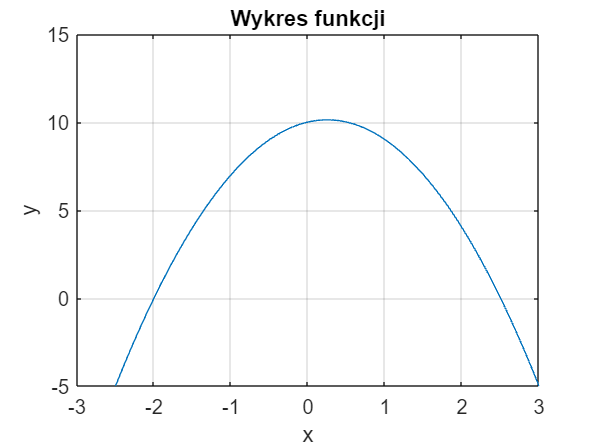

% y=-2*x.^2+x+10;
%plot(x,y)
plot(x,p)
grid on;
ylim([-5 15])
title('Wykres funkcji');
xlabel('x');
ylabel('y');


%Całkowanie numeryczne metodą prostokątów
a=-2; %dolna granica całkowania
b=2.5; %górna granica całkowania
n=10; %liczba przedziałów
h=(b-a)/n; %szerokość przedziałów
x=(a+h/2):h:(b-h/2); %węzły w środku podprzedziału
%x=(a):h:(b-h); %węzły na początku podprzedziału
%x=(a+h):h:(b); %węzły na końcu podprzedziału
y=-2*x.^2+x+10; %funkcja całkoawna
pole_prostokaty=h*sum(y) %całkowanie numeryczne (sumowanie pól)

pole_prostokaty = 30.5269

2. f(x) = (2x^(1/x)+3x^2)/(3*(2x+1)^2 tabela wartości i narysować w przedziale <2,1 4pi/3> (dla 50 wartości zmiennej niezależnej)

x = linspace(2.1,4*pi/3,50)';
y = (2*x.^(1./x)+3*x.^2)./(3*(2*x+1).^2)

y =     0.1982
    0.1984
    0.1986
    0.1988
    0.1991
    0.1993
    0.1995
    0.1998
    0.2000
    0.2002


table(x,y)

ans = 50×2 table
      x          y   
    ______    _______

       2.1    0.19819
    2.1426    0.19841
    2.1853    0.19862
    2.2279    0.19884
    2.2705    0.19906
    2.3131    0.19929
    2.3558    0.19952
    2.3984    0.19976
     2.441    0.19999
    2.4837    0.20023
    2.5263    0.20048
    2.5689    0.20072
    2.6115    0.20097
    2.6542    0.20122
    2.6968    0.20147
    2.7394    0.20173


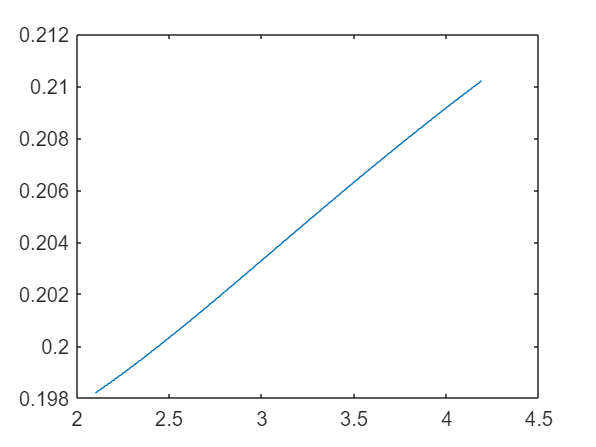

plot(x,y)

Zad 3. Najmniejszy dodatni pierwiastek

x0=0;
fun=@f;
pierwiastek=fzero(fun,x0)

pierwiastek = 0.3083

Zad4

A=[1 -2 1 -1 1;2 1 2 3 4;2 2 1 2 3;2 2 2 1 2;2 5 -2 2 1]

A =      1    -2     1    -1     1
     2     1     2     3     4
     2     2     1     2     3
     2     2     2     1     2
     2     5    -2     2     1


Y=[1 10 11 6 3]'

Y =      1
    10
    11
     6
     3


X=A\Y

X =    -8.7619
    4.4762
   -0.7619
   -7.6190
   11.8571


W=det(A)

W = -21.0000

A_odwrotna=inv(A)

A_odwrotna =     0.8095    1.1429   -2.4286    0.5238    0.8571
   -0.3810   -0.7143    1.1429    0.0476   -0.2857
   -0.1905    0.1429   -0.4286    0.5238   -0.1429
    0.0952    1.4286   -2.2857    0.2381    0.5714
   -0.2857   -1.2857    2.8571   -0.7143   -0.7143


A_odwrotna(4,2)

ans = 1.4286

function y=f(x)
e=exp(1);
y=2*x^2-3*x+e^(-x);
end